# Assignment 1

rng(10)
addpath('functions')


## Question 1.1

s.A = [1, -3.88098254, 5.64726905, -3.6515443, 0.88525793];
s.B = [0.4453368,-1.71110786,2.49838163, -1.64272524, 0.41012833];


## Question 1.2

## Question 1.3

Stable with no stochastic term:

eigs = roots(A)

eigs =    0.9902 + 0.0000i
   0.9947 + 0.0000i
   0.9480 + 0.0005i
   0.9480 - 0.0005i


abs(eigs)

ans =     0.9902
    0.9947
    0.9480
    0.9480


## Question 1.4

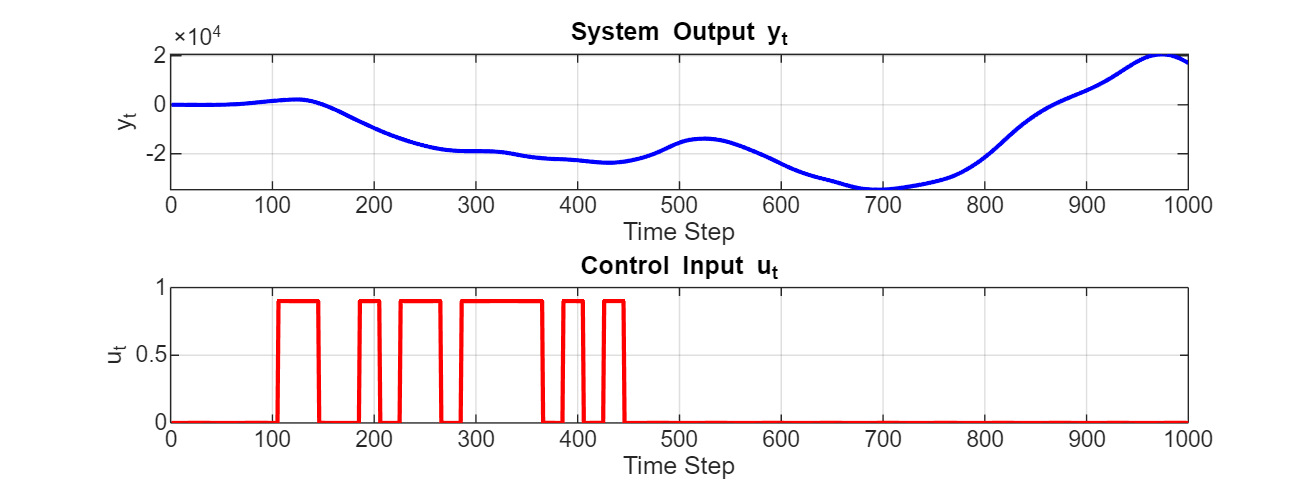

s.u_data = readmatrix('Assignment1_ObservationsAndInputs.txt')';
%% System Parameters
s.N = 1000;  % Number of time steps
s.sigma_e = 0.1;  % Standard deviation of process noise
s.k = 1;  % Input delay
s.alpha = 0.5; % Gain for P ctrl
n_max = max([length(s.A),length(s.B)]);
s.u_init = zeros(n_max,1);
s.y_init = zeros(n_max,1);

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], u_data(:,2) [4], Off [5])
SP = 1;
Stochastic = 1;
ctrl = 4;
s = run_case(s, SP, Stochastic, ctrl);

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
plot(s.y, 'b', 'LineWidth', 1.5);
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

## Question 1.7

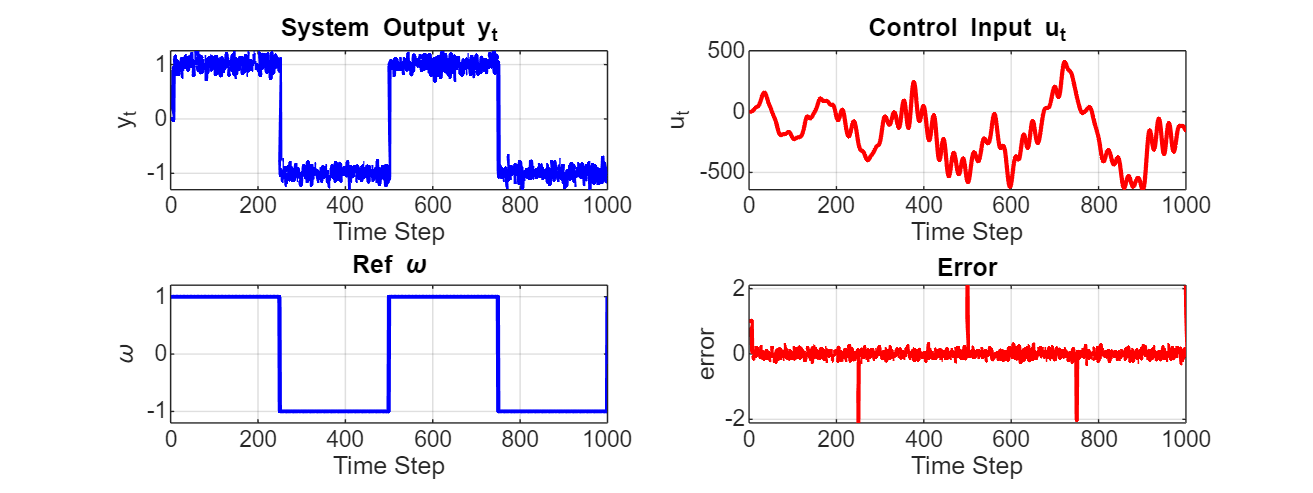

s.u_data = readmatrix('Assignment1_ObservationsAndInputs.txt')';
%% System Parameters
s.N = 1000;  % Number of time steps
s.sigma_e = 0.1;  % Standard deviation of process noise
s.k = 1;  % Input delay
s.alpha = 0.5; % Gain for P ctrl
n_max = max([length(s.A),length(s.B)]);
s.u_init = zeros(n_max,1);
s.y_init = zeros(n_max,1);

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], u_data(:,2) [4], Off [5])
SP = 3;
Stochastic = 1;
ctrl = 3;
s = run_case(s, SP, Stochastic, ctrl);

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,2,1);
plot(s.y, 'b', 'LineWidth', 1.5);
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,2,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;
subplot(2,2,3)
plot(s.omega, 'b', 'LineWidth', 1.5);
title('Ref \omega');
ylim([-max(omega)*1.2,max(omega)*1.2])
xlabel('Time Step');
ylabel('\omega');
grid on;
subplot(2,2,4)
plot(s.omega-s.y, 'r', 'LineWidth', 1.5);
title('Error');
xlabel('Time Step');
ylabel('error');
grid on;